# Start End Marker

Marks the doy of start and end of disturbance.

For faster performance.

## I / O

clear
clc
% Choose mask file.
[File, Path]=uigetfile({'*.tif'},'Choose mask file.','Multiselect','off','/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[mask, R0] = geotiffread(strcat(Path, File));
[x,y] = size(mask);

% Counter image.
distCounterImg = zeros(x,y);
tempCounter = zeros(x,y);

% Choose time series imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/');
[~, fileLength] = size(file);

% Output directory
selected_dir = uigetdir('/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/distStart/','Disturbance time output');


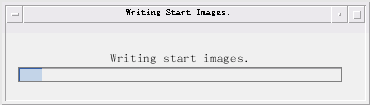

tic
% Read & mask time series images and batch NDVI.
f = waitbar(0,'starting...','Name','Writing Start Images.');

% for counter = 1:14
counter = 1;
    startMarker = zeros(x,y);
    startMarkerMonth = zeros(x,y);
    counterIM = zeros(x,y);
    
    for num = 2:fileLength-1
        prevIM = geotiffread(strcat(path,char(file(num-1))));
        currentIM = geotiffread(strcat(path,char(file(num))));
        nextIM = geotiffread(strcat(path,char(file(num+1))));
        
        currentName = char(file(num));
        currentYear = str2num(currentName(5:8));
        currentDOY = str2num(currentName(9:11));
        [year, month, ~, ~, ~] = datevec(datenum(currentYear,1,currentDOY));
        
        DOYtemp = char(file(num));
        DOYtemp = DOYtemp(1:end-4);
        doy = doyDiff(1987000,str2num(DOYtemp));
        
        tempCounter = ((currentIM - prevIM) > 0.5) & ((nextIM - prevIM) > 0.5);
        counterIM = counterIM + tempCounter;
        
%         startMarker(round(tempCounter) == 1 & startMarker == 0 & round(counterIM) == counter) = year;
        startMarkerMonth(round(tempCounter) == 1 & startMarkerMonth == 0 & round(counterIM) == counter) = month;
        
%         endMarker(prevIM == 1 & currentIM == 0 & isnan(endMarker)) = doy;
%         geotiffwrite(strcat(selected_dir,'/distEnd',num2str(counter)),endMarker,R0,'CoordRefSysCode',32649);
    
%     geotiffwrite(strcat(selected_dir,'/distStart_',DOYtemp),sDate,R0,'CoordRefSysCode',32649);
    end
    

    waitbar(counter / 14,f,'Writing start images.');

    geotiffwrite(strcat(selected_dir,'/distStartYr',num2str(counter)),startMarker,R0,'CoordRefSysCode',32649);
    geotiffwrite(strcat(selected_dir,'/distStartMth',num2str(counter)),startMarkerMonth,R0,'CoordRefSysCode',32649);
    clear startMarker startMarkerMonth counterIM prevIM currentIM;
    
% end
toc

时间已过 306.759846 秒。


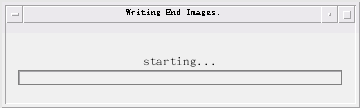


tic
f = waitbar(0,'starting...','Name','Writing End Images.');


% for counter = 1:14
%     endMarker = zeros(x,y);
%     counterIM = zeros(x,y);
%     for num = 2:fileLength      % Search for the whole series.
%         prevIM = geotiffread(strcat(path,char(file(num-1))));
%         currentIM = geotiffread(strcat(path,char(file(num))));
%         startMarker = geotiffread(strcat(selected_dir,'/distStart',num2str(counter)));
%         
%         DOYtemp = char(file(num-1));
%         DOYtemp = DOYtemp(1:end-4);
%         doy = doyDiff(1987000,str2num(DOYtemp));
%         
%         tempCounter = (prevIM - currentIM) > 0.5 & startMarker < doy;
%         counterIM = counterIM + tempCounter;
%         
% 
%         endMarker(tempCounter == 1 & endMarker == 0 & round(counterIM) == counter) = doy;
% %         endMarker(endMarker<= startMarker) = nan;   % Disturbance should end later than start.
%     end
%     waitbar(counter / 14,f,'Writing end images.');
%     geotiffwrite(strcat(selected_dir,'/distEnd',num2str(counter)),endMarker,R0,'CoordRefSysCode',32649);
%     clear endMarker;
% end
% toc

% geotiffwrite('/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/distCounter.tif',distCounterImg,R0,'CoordRefSysCode',32649)
